% Euler's Method
m=@(x,y) y-3.*x;
yexact=@(x) 7*exp(x)+3*x+3;

y0=10

y0 = 10

x0=0

x0 = 0

xf=3

xf = 3

h=1

h = 1


x=x0:h:xf

x =      0     1     2     3


y=zeros(size(x))

y =      0     0     0     0


y(1)=y0

y =     10     0     0     0


err=zeros(size(x))

err =      0     0     0     0


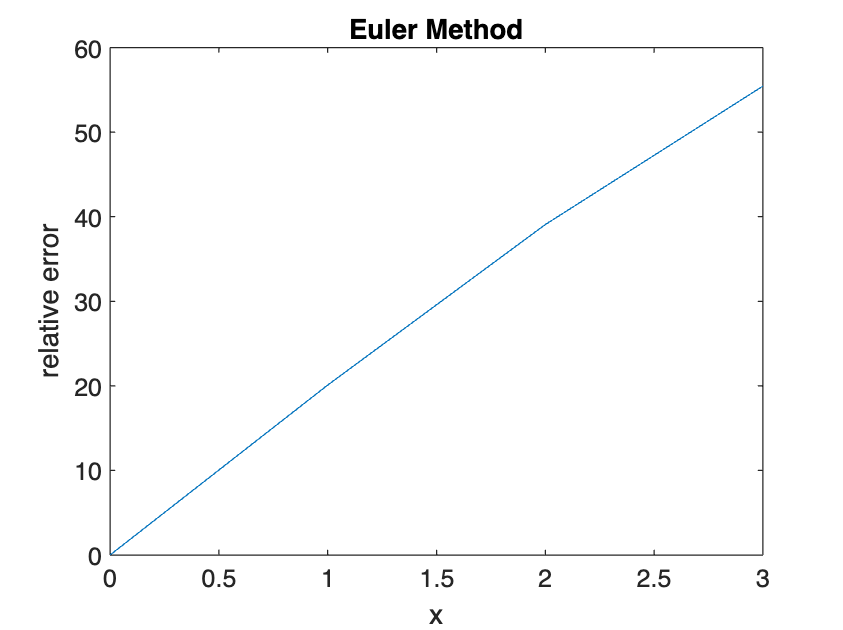


for i=1:length(x)-1
    y(i+1)=y(i)+h*m(x(i),y(i));
    err(i+1)=abs((yexact(x(i+1))-y(i+1))/yexact(x(i+1)))*100;
end
y_euler = y;  % <-- Guarda el resultado de Euler aquí

plot(x,err)
title("Euler Method")
xlabel("x")
ylabel("relative error")

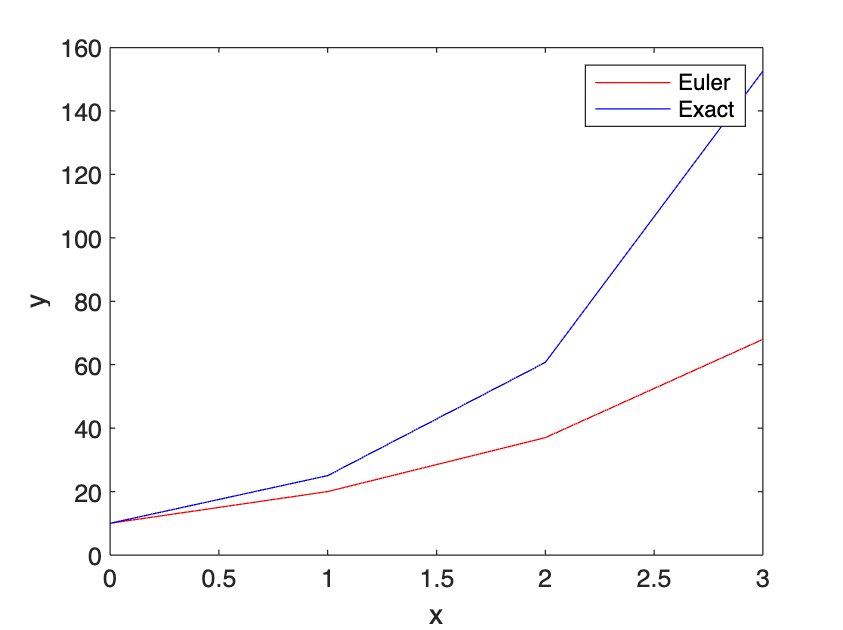


plot(x,y,'r')
hold on
plot(x,yexact(x),'b')
hold off
xlabel("x")
ylabel("y")
legend("Euler","Exact")

y1st=y;

% 1st improvement over Euler's Method
m=@(x,y) y-3.*x;
yexact=@(x) 7*exp(x)+3*x+3;

y0=10

y0 = 10

x0=0

x0 = 0

xf=3

xf = 3

h=1

h = 1


x=x0:h:xf

x =      0     1     2     3


y=zeros(size(x))

y =      0     0     0     0


y(1)=y0

y =     10     0     0     0


err2=zeros(size(x))

err2 =      0     0     0     0


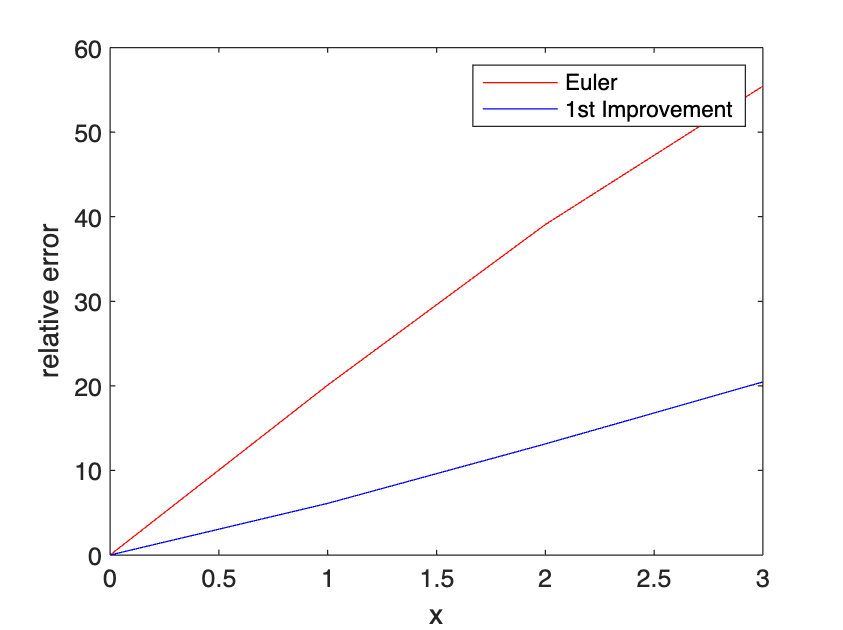


for i=1:length(x)-1
    mi=m(x(i),y(i));
    ypred=y(i)+h*mi;
    mf=m(x(i+1),ypred);
    m_avg=(mi+mf)/2;
    y(i+1)=y(i)+h*m_avg;
    err2(i+1)=abs((yexact(x(i+1))-y(i+1))/yexact(x(i+1)))*100;
end

plot(x,err,'r')
hold on
plot(x,err2,'b')
hold off
legend("Euler","1st Improvement")
xlabel("x")
ylabel("relative error")

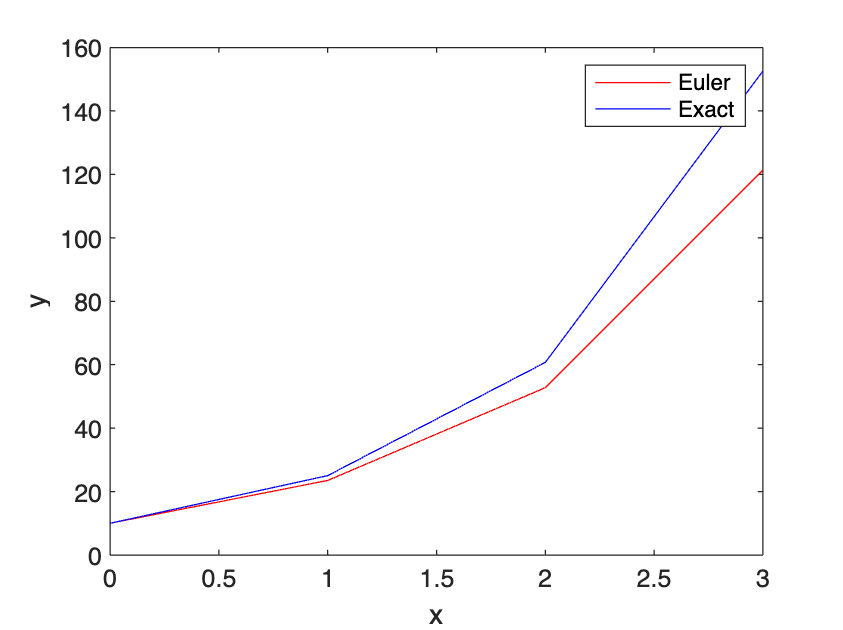


plot(x,y,'r')
hold on
plot(x,yexact(x),'b')
hold off
xlabel("x")
ylabel("y")
legend("Euler","Exact")

y1st=y;

% 2nd improvement over Euler's Method
m=@(x,y) y-3.*x;
yexact=@(x) 7*exp(x)+3*x+3;

y0=10

y0 = 10

x0=0

x0 = 0

xf=3

xf = 3

h=1

h = 1


x=x0:h:xf

x =      0     1     2     3


y=zeros(size(x))

y =      0     0     0     0


y(1)=y0

y =     10     0     0     0


err2=zeros(size(x))

err2 =      0     0     0     0


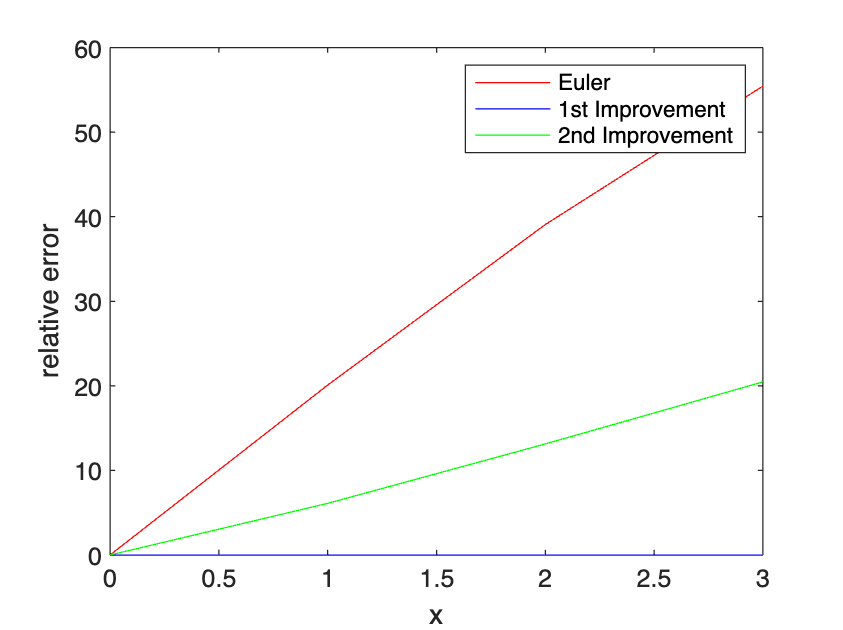


for i=1:length(x)-1
    mi=m(x(i),y(i));
    ypred=y(i)+h/2*mi;
    m_mid=m(x(i)+h/2,ypred);

    y(i+1)=y(i)+h*m_mid;
    err3(i+1)=abs((yexact(x(i+1))-y(i+1))/yexact(x(i+1)))*100;
end

clf
plot(x,err,'r')
hold on
plot(x,err2,'b')
plot(x,err3,'g')
hold off
legend("Euler","1st Improvement", "2nd Improvement")
xlabel("x")
ylabel("relative error")

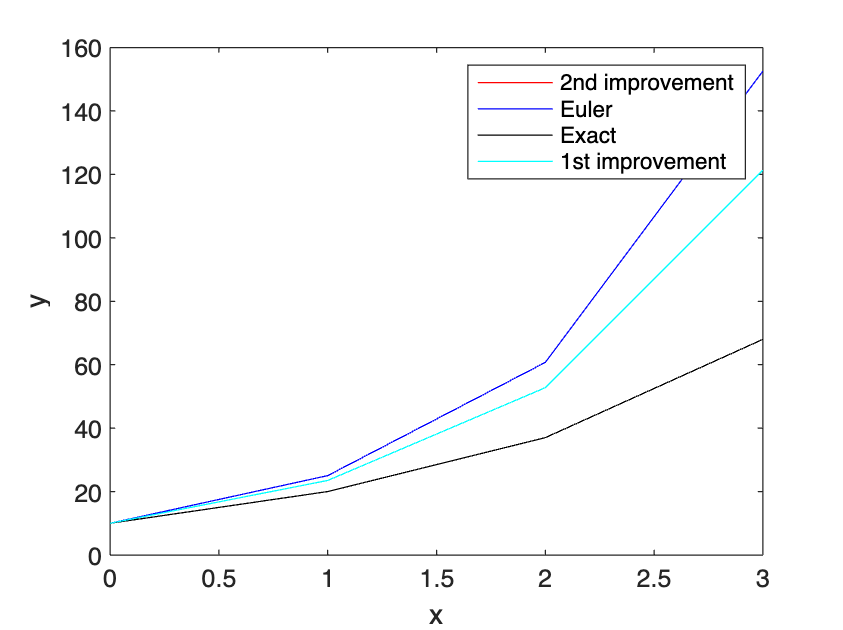


plot(x,y,'r')
hold on
plot(x,yexact(x),'b')
plot(x,y_euler,'k')
plot(x,y1st,'C')


hold off
xlabel("x")
ylabel("y")
legend("2nd improvement","Euler","Exact","1st improvement")

y2nd = y;

m=@(x,y) y-3.*x;
yexact=@(x) 7*exp(x)+3*x+3;

y0=10

y0 = 10

x0=0

x0 = 0

xf=3

xf = 3

h=1

h = 1


x=x0:h:xf

x =      0     1     2     3


y=zeros(size(x))

y =      0     0     0     0


y(1)=y0

y =     10     0     0     0


err4=zeros(size(x))

err4 =      0     0     0     0



% Vegeta 777 Method
a2 = 7;
a1=1-a2;
q=1/(2*a2)

q = 0.0714

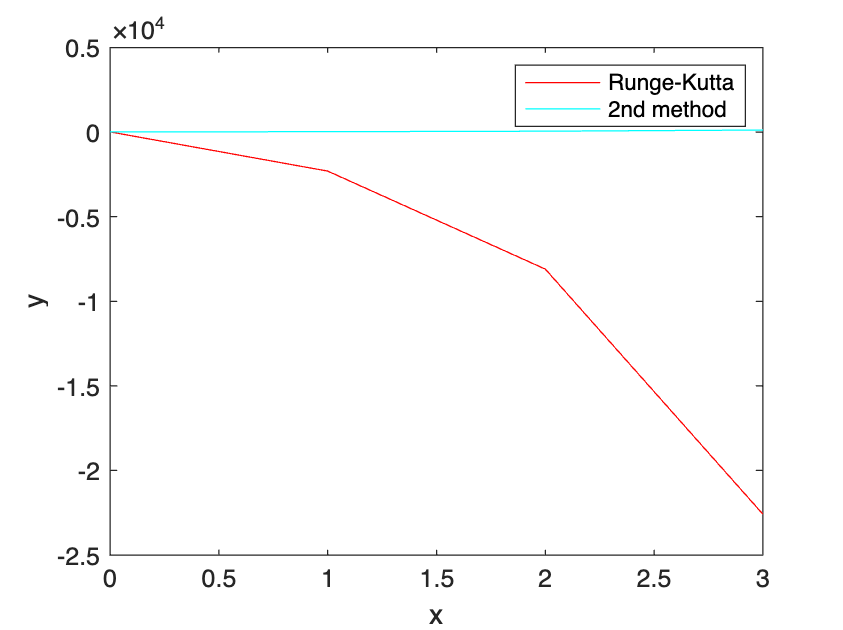


for i=1:length(x)-1
    k1=m(x(i),y(i));
    k2=m(x(i)+1*h,y(i)+q*k1*h);

    y(i+1)=y(i)+(a1*k1+a2*k2);
    err4(i+1)=abs((yexact(x(i+1))-y(i+1))/yexact(x(i+1)))*100;
end

clf
plot(x,y,'r')
hold on
plot(x,y2nd,'c')
hold off
legend("Runge-Kutta", "2nd method")
xlabel("x")
ylabel("y")